problem 1

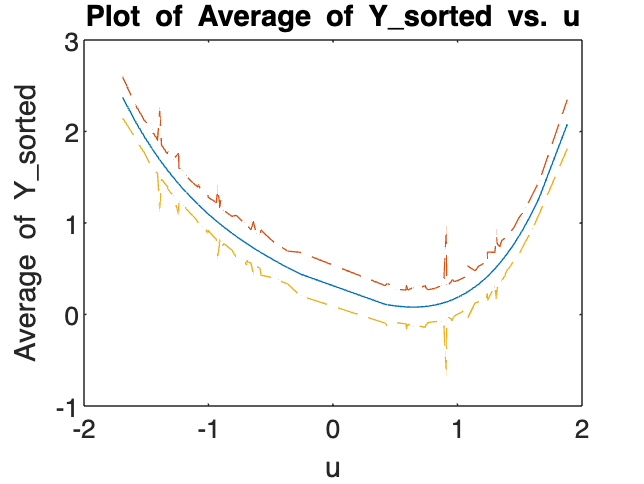

clc
clear

% Define your parameters
theta = [0.3, -0.5, 0.5, 0.2, 0.4];
u_mean = 1;
u_variance = 0.12;

% Initialize a matrix to store all the Y values
Y_all = zeros(100, 100);


% Generate half of u values from N(u_mean, u_variance)
half_size = 100/2;
u_half1 = -u_mean + sqrt(u_variance) * randn(half_size, 1);

% Generate half of u values from N(-u_mean, u_variance)
u_half2 = u_mean + sqrt(u_variance) * randn(half_size, 1);
u = [u_half1; u_half2];

% Generate X matrix
X = [ones(100,1), u, u.^2/2, u.^3/3, u.^4/4];

for i = 1:100
    % Generate noise N(mu, sigma)
    N = randn(100, 1);

    % Calculate Y
    Y = X * theta' + N;
    
    % Store Y in the matrix
    Y_all(:, i) = Y;
end

% Perform LS estimation
theta_hat_LS = (X' * X)^-1 * X' * Y_all;

 % Calculate Y_hat
 Y_hat = X * theta_hat_LS;

% Sort X
[X_sorted, idx] = sort(X(:, 2)); % Sorting according to the second column (u)
%X_sorted = X(idx, :);
 
% Sort Y according to the indexes of sorted X
Y_sorted = Y_hat(idx,:);
 
% Calculate the average of each column of Y_sorted
Y_avg = mean(Y_sorted, 2); 
 
% Calculate the variance along columns (variance of each row)
variance_along_columns = (std(Y_hat, 0, 2));

% Plot the average of Y_sorted with respect to u
figure;
plot(X_sorted, Y_avg, '-');
xlabel('u');
ylabel('Average of Y\_sorted');
title('Plot of Average of Y\_sorted vs. u');
hold on
plot(X_sorted, Y_avg + variance_along_columns , '--');
plot(X_sorted, Y_avg - variance_along_columns , '--');
%scatter(u(idx, :),Y_sorted)
%errorbar(u(idx(1:10:end), :), Y_sorted(1:10), variance_along_columns(1:10), 'o-');
%boxplot()
hold off

problem 2

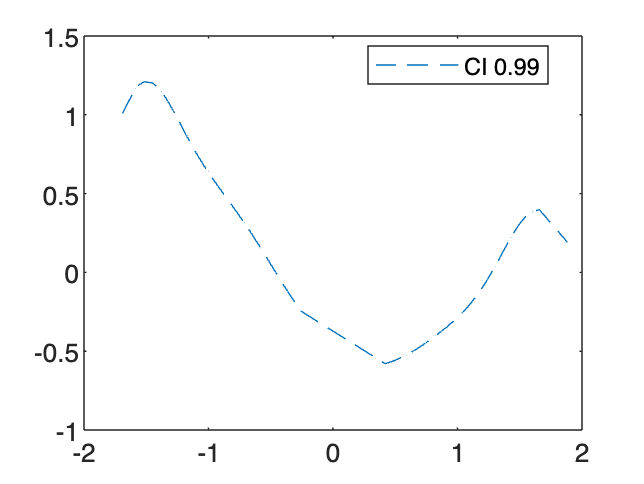

% Calculate the standard deviation along columns
std_dev = std(Y_sorted, 0, 2);

% Calculate confidence intervals for 90%, 95%, and 99%
alpha = [0.1, 0.05, 0.01];
for i = 1:length(alpha)
    z = abs(norminv(alpha(i)/2));
    CI = z * std_dev;
    plot(X_sorted, Y_avg + CI , '--', 'DisplayName', ['CI ' num2str(1-alpha(i))]);
    plot(X_sorted, Y_avg - CI , '--', 'DisplayName', ['CI ' num2str(1-alpha(i))]);
end
legend('Location', 'best');